# **Taller 14**

Lea la imagen `"plate_side.jpg"` y visualicela.

I = imread('plate_side.jpg');
figure();imshow(I);title('Plate Side Car','interpreter','latex');

Recupere los 4 pares de coordenadas $(x_{i},y_{i})$correspondientes al area que comprende la placa del vehiculo (utilice alguna herramienta interactiva que permita recuperara las coordenadas dando click en la imagen), para aplicar una transformación proyectiva.

movingpoints = [224 201; 516 241; 508 340; 226 275];

Cargue la imagen `"plate_reference.jpg" `y visualicela.

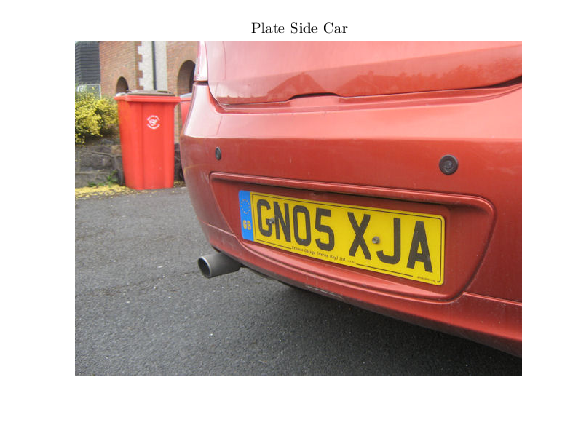

R = imread('plate_reference.jpg');
figure();imshow(R);title('Reference Plate','interpreter','latex');

Recupere los 4 pares de coordenadas $(x_{i},y_{i})$correspondientes al area amarilla y celeste que comprende una placa del vehiculo (utilice alguna herramienta...)

fixedpoints=[17 13; 501 13; 501 127; 17 127];                         

Aplique la transformación proyectiva a la imagen original a partir de los 2 conjuntos de puntos y visualicela. 

tform = cp2tform(movingpoints,fixedpoints,'projective');    
J = imtransform(I,tform);

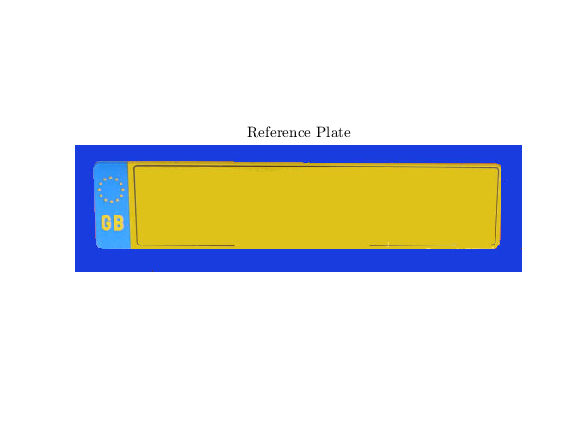

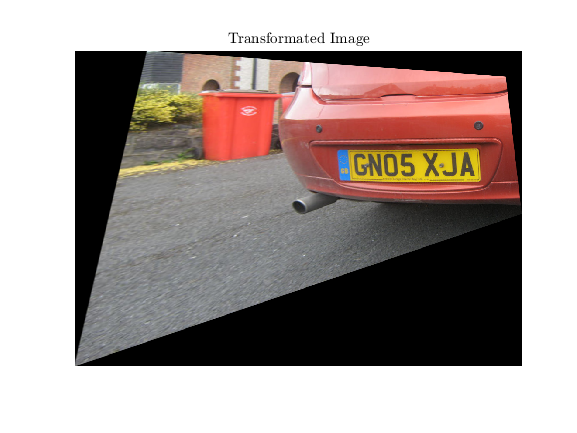

figure;
imshow(J);title('Transformated Image','Interpreter',"latex");

Finalmente, recorte el area de interes de la imagen transformada (la placa del vehiculo), que despues de la transformación deberia verse como si la imagen ubiera sido captada de frente, a un angulo de 90° con el eje optico de la camara.

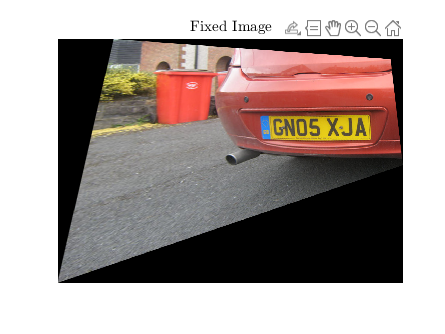

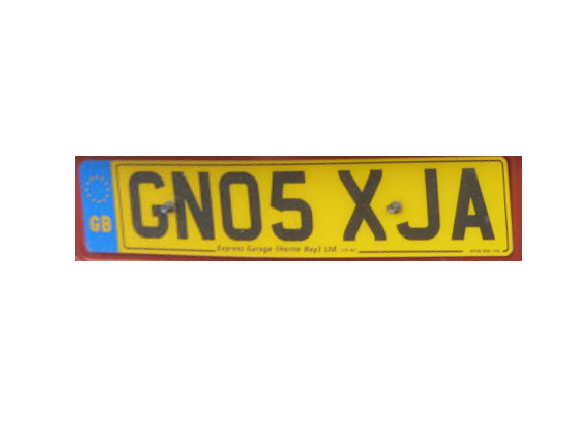

crop_img = imcrop(J);
figure();imshow(crop_img);title('Fixed Image','interpreter','latex');